# EL2520 Computer Exercise 4

## 3.3 | Glover-McFarlane robust loop-shaping

### 3.3.1 | Design dynamic decoupling (reuse 3.2.1 & 3.2.2)

s = tf('s');
% sys = minphase;
sys = nonminphase;
% Remember to change omega_cd in 3.1.2 to correspond to sys
% AND negate W_1 if using nonminphase

A = sys.A;
B = sys.B;
C = sys.C;
D = sys.D;

I = eye(size(A));
G = minreal(C*inv(s*I-A)*B+D); % 2x2 trans. func.
g11 = G(1,1);
g12 = G(1,2); % Input 2 to output 1
g21 = G(2,1); % Input 1 to output 2
g22 = G(2,2);

% RGA
G_inv = minreal(inv(G));
rga = minreal(G*transpose(G_inv));
rga_zero = freqresp(rga,0)

rga_zero =     0.6806    0.2214
   -0.2086    1.4015


% RGA shows we can use same coupling in controller F for minphase and nonminphase

w12 = -g12/g11;
w21 = -g21/g22;
% W_1 = minreal([1, w12; w21, 1])
W_1 = -minreal([1, w12; w21, 1])


W_1 =
 
  From input 1 to output...
   1:  -1
 
          0.175
   2:  -----------
       s + 0.09089
 
  From input 2 to output...
         0.1238
   1:  -----------
       s + 0.08582
 
   2:  -1
 
Continuous-time transfer function.




W_2 = eye(size(G));

G_tilde = minreal(W_2*G*W_1);
% G_tilde_alt = minreal([(g11-minreal(g12*minreal(g21/g22))), 0; 0, (g22 - minreal(g12*minreal(g21/g11)))]);

G_tilde(1,2) = 0; 
G_tilde(2,1) = 0;
% By setting the off diagonal elements to zero (they are already close)
% We confirm that the other method of calcualting G_tilde is exactly the same

G_tilde


G_tilde =
 
  From input 1 to output...
         -0.02088 s^2 - 0.00369 s + 0.0002896
   1:  ----------------------------------------
       s^3 + 0.2278 s^2 + 0.01682 s + 0.0003983
 
   2:  0
 
  From input 2 to output...
   1:  0
 
        -0.01808 s^2 - 0.003194 s + 0.0002507
   2:  ---------------------------------------
       s^3 + 0.2236 s^2 + 0.01609 s + 0.000366
 
Continuous-time transfer function.



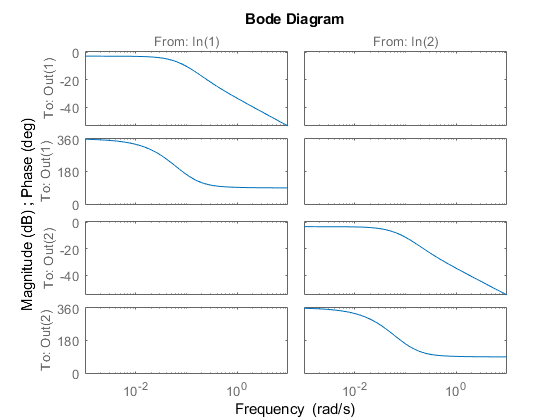

% G_tilde_alt
bode(G_tilde)

% bode(G_tilde_alt)

%%% Design decoupled PI controller

% Given design criteria
p_m = pi/3; % phi_m [rad]
% w_cd = 0.1; % omega_c,d minphase [rad/s] 
w_cd = 0.02; % omega_c,d nonminphase [rad/s] 

g11 = G_tilde(1,1);
g22 = G_tilde(2,2);

[m11,p11] = bode(g11, w_cd); % Amplitude and phase of system at w_cd
[m22,p22] = bode(g22, w_cd); % Amplitude and phase of system at w_cd

T11 = (1/w_cd)*tan(-pi + pi/2 + p_m - deg2rad(p11)); 
T22 = (1/w_cd)*tan(-pi + pi/2 + p_m - deg2rad(p22));

l11 = g11*(1 + 1/(s*T11));
l22 = g22*(1 + 1/(s*T22));

[m1, p1] = bode(l11,w_cd);
[m2, p2] = bode(l22,w_cd);

K1 = 1/m1;
K2 = 1/m2;

f1 = K1*(1 + 1/(s*T11));
f2 = K2*(1 + 1/(s*T22));

F_tilde = minreal([f1, 0; 0, f2])


F_tilde =
 
  From input 1 to output...
       0.751 s + 0.02517
   1:  -----------------
               s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       0.8465 s + 0.02655
   2:  ------------------
               s
 
Continuous-time transfer function.



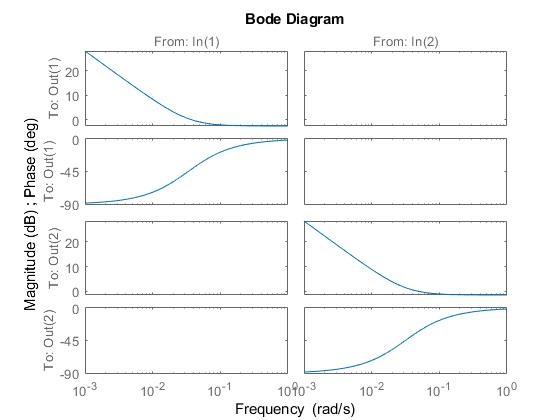

bode(F_tilde)


L_0 = minreal(G*minreal(W_1*F_tilde));
L_0(1,2) = 0; 
L_0(2,1) = 0;

% [Gm,Pm,wp,wc] = margin(L_0(1,1)) % Phase margin, amplitude margin, and corresp. freqs. of G_d
% [Gm,Pm,wp,wc] = margin(L_0(2,2)) % Phase margin, amplitude margin, and corresp. freqs. of G_d

L_0


L_0 =
 
  From input 1 to output...
       -0.01568 s^3 - 0.003296 s^2 + 0.0001246 s + 7.287e-06
   1:  -----------------------------------------------------
           s^4 + 0.2278 s^3 + 0.01682 s^2 + 0.0003983 s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       -0.0153 s^3 - 0.003184 s^2 + 0.0001274 s + 6.655e-06
   2:  ----------------------------------------------------
           s^4 + 0.2236 s^3 + 0.01609 s^2 + 0.000366 s
 
Continuous-time transfer function.



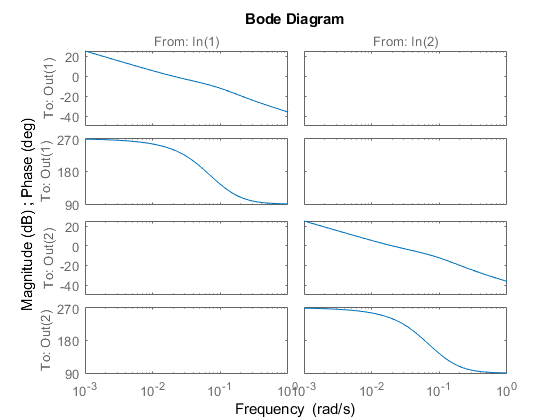

bode(L_0)


% I = eye(size(G));
% S_0 = minreal(inv(minreal(I + L_0)));
% T_0 = minreal(S_0*L_0);
% 
% bode(S_0,T_0)

### 3.3.2 | Robust Loop Shaping


alpha = 1.1;
[Fr,gam] = rloop(L_0,alpha);

[num_Fr,den_Fr] = tfdata(Fr,'v');
Fr_tf = minreal(tf(num_Fr,den_Fr));
Fr_tf(1,2) = 0;
Fr_tf(2,1) = 0;

Fr_tf


Fr_tf =
 
  From input 1 to output...
          0.1135 s^3 + 0.0257 s^2 + 0.001876 s + 4.375e-05
   1:  ------------------------------------------------------
       s^4 + 0.3352 s^3 + 0.04697 s^2 + 0.003415 s + 7.37e-05
 
   2:  0
 
  From input 2 to output...
   1:  0
 
          0.1127 s^3 + 0.02507 s^2 + 0.001781 s + 3.985e-05
   2:  -------------------------------------------------------
       s^4 + 0.3304 s^3 + 0.04554 s^2 + 0.003254 s + 6.713e-05
 
Continuous-time transfer function.



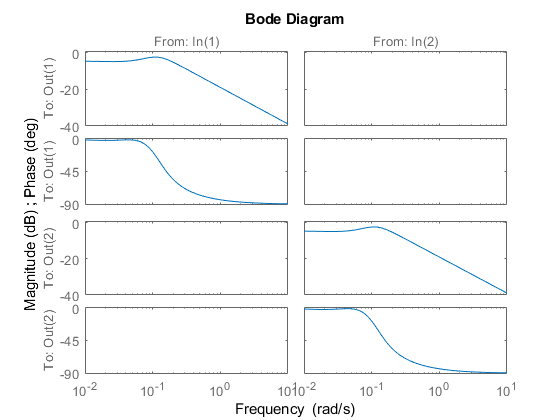

bode(Fr_tf)


F = minreal(W_1*minreal(F_tilde*Fr_tf))


F =
 
  From input 1 to output...
       -0.08521 s^4 - 0.02216 s^3 - 0.002055 s^2 - 8.005e-05 s - 1.101e-06
   1:  -------------------------------------------------------------------
           s^5 + 0.3352 s^4 + 0.04697 s^3 + 0.003415 s^2 + 7.37e-05 s
 
          0.01491 s^4 + 0.003877 s^3 + 0.0003597 s^2 + 1.401e-05 s + 1.926e-07
   2:  ---------------------------------------------------------------------------
       s^6 + 0.4261 s^5 + 0.07744 s^4 + 0.007684 s^3 + 0.0003841 s^2 + 6.698e-06 s
 
  From input 2 to output...
          0.01182 s^4 + 0.002998 s^3 + 0.0002691 s^2 + 1.003e-05 s + 1.31e-07
   1:  --------------------------------------------------------------------------
       s^6 + 0.4162 s^5 + 0.0739 s^4 + 0.007163 s^3 + 0.0003464 s^2 + 5.761e-06 s
 
       -0.09542 s^4 - 0.02421 s^3 - 0.002173 s^2 - 8.102e-05 s - 1.058e-06
   2:  -------------------------------------------------------------------
           s^5 + 0.3304 s^4 + 0.04554 s^3 + 0.003254 s^2 + 6.713e-05 s
 
C

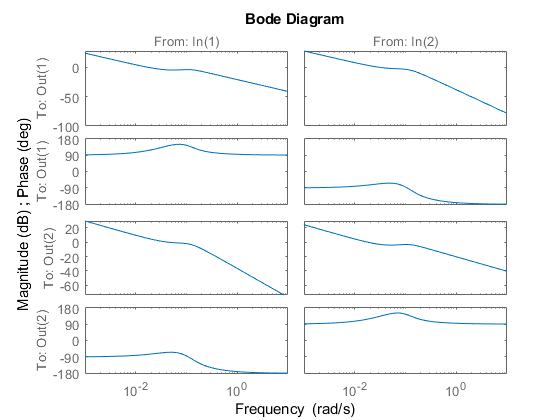

bode(F)

### 3.3.3 | Sensitivity & Complimentary Sensitivity

I = eye(size(G));
L = minreal(G*F);
L(1,2) = 0; 
L(2,1) = 0;

L


L =
 
  From input 1 to output...
                                                                                                                                                                          
       -0.001779 s^11 - 0.001464 s^10 - 0.0005142 s^9 - 0.0001016 s^8 - 1.219e-05 s^7 - 8.366e-07 s^6 - 1.879e-08 s^5 + 1.877e-09 s^4 + 1.895e-10 s^3 + 7.637e-12 s^2     
                                                                                                                                                                          
                                                                                                                                                  + 1.51e-13 s + 1.199e-15
                                                                                                                                                                          
   1:  -------------------------------------------------------------------------------------------------------


S = minreal(inv(minreal(I + L)));
T = minreal(S*L);


[Gm,Pm,wp,wc] = margin(L(1,1)) % Phase margin, amplitude margin, and corresp. freqs. of G_d

Gm = 3.7620

Pm = 71.8875

wp = 0.0590

wc = 0.0111

[Gm,Pm,wp,wc] = margin(L(2,2)) % Phase margin, amplitude margin, and corresp. freqs. of G_d

Gm = 3.7607

Pm = 71.9756

wp = 0.0586

wc = 0.0110

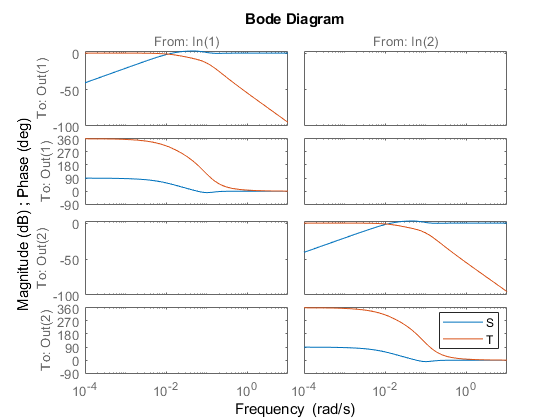


bode(S,T)
legend

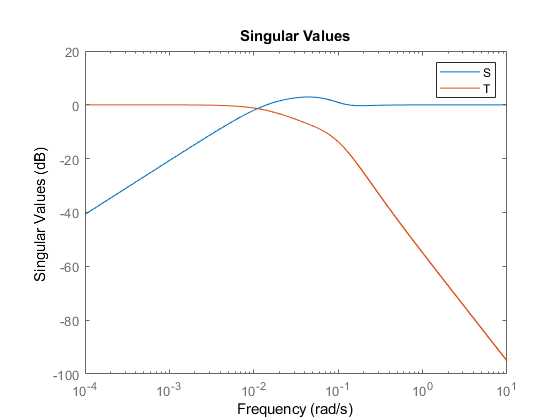

% Singular values
sigma(S, T)
legend

max(sigma(S),[],2)

ans =     1.3983
    1.3983


max(sigma(T),[],2)

ans =     1.0000
    1.0000


### 3.3.4 | Closed Loop Simulation

closedloop

% %%%% Saves prior plot as pdf filling up page %%%%
% set(1, 'PaperPosition', [0 0 5 5]); %Position plot at left hand corner with width 5 and height 5.
% set(1, 'PaperSize', [5 5]); %Set the paper to have width 5 and height 5.
% saveas(1, 'test', 'pdf')
% %%%% Saves prior plot as pdf filling up page %%%%